Console preparation

clc;
close all; 
warning('off', 'all');

Import the data for the step response of the fan

open('251125stepresponse.fig'); 
a = get(gca,'Children');  
obj_r = a(2);  
x_step_response = obj_r.XData;
y_step_response = obj_r.YData; 
close(gcf);

open('251125rpm_ramp.fig'); 
b = get(gca,'Children');  
obj_r_alpha2 = b(2);  
x_rpm_ramp = obj_r_alpha2.XData;
y_rpm_ramp = obj_r_alpha2.YData; 
close(gcf);

open('251125height_ramp.fig'); 
b = get(gca,'Children');  
obj_r_alpha2 = b(2);  
x_height_ramp = obj_r_alpha2.XData;
y_height_ramp = obj_r_alpha2.YData; 
close(gcf);

# Variable definitions

g = 9.81;
rotations_at_ss = 4200;

# Linear regression of duty_cycle/rpm

duty_cycle =    [0      5       7.5     10      20      40      50];
rpm     =       [3020   3750    4000    4300    5450    7200    8000];
polyfit_of_w = polyfit(duty_cycle, rpm, 1);
m = polyfit_of_w(1);
d = polyfit_of_w(2);
ktau_from_rpm_ramp = m

ktau_from_rpm_ramp = 97.8373

u_0 = ((-d/m)/100)*5

u_0 = -1.6614

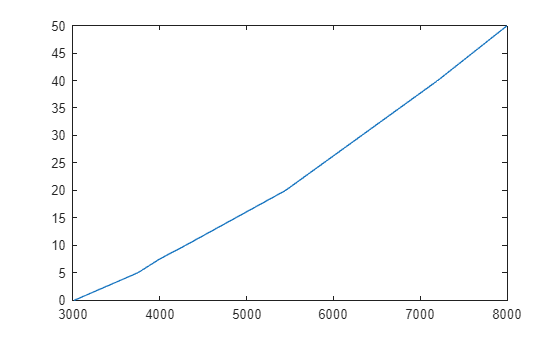

plot(rpm,duty_cycle);

# Step response of the real System

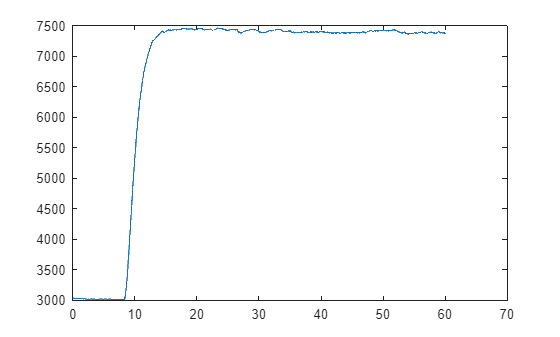

time_limit_sr = max(x_step_response) - 60; 
idx_sr = x_step_response >= time_limit_sr;
x_step_response = x_step_response(idx_sr);
y_step_response = y_step_response(idx_sr);
t_r = x_step_response(:);
Ts_r = mean(diff(t_r));
y_rotations = y_step_response;
plot(t_r,y_step_response);

tau_omega = 10.35 - 8.385

tau_omega = 1.9650

# Transition from one floating point to another floating point to get zdot and rpm 

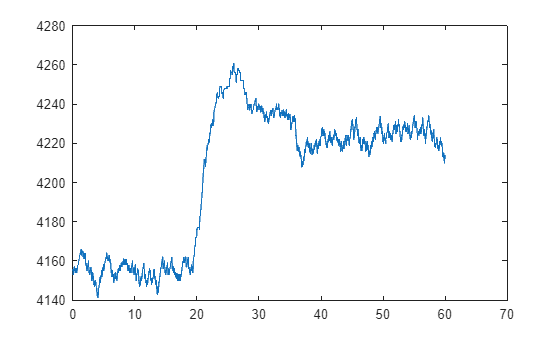

time_limit_cw = max(x_rpm_ramp)-60; 
idx_cw = x_rpm_ramp >= time_limit_cw;
x_rpm_ramp = x_rpm_ramp(idx_cw);
y_rpm_ramp = y_rpm_ramp(idx_cw);
t_cw = x_rpm_ramp(:);        
Ts_cw = mean(diff(t_cw));    
plot(t_cw,y_rpm_ramp);

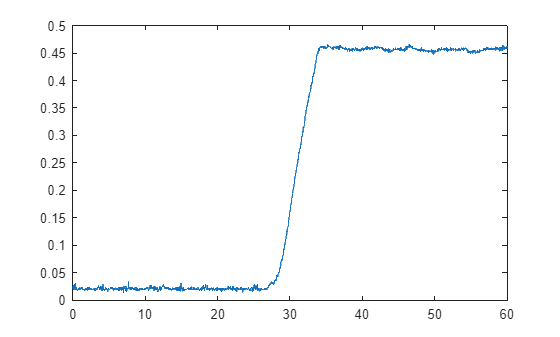

time_limit_height = max(x_height_ramp) - 60;
idx_height = x_height_ramp >= time_limit_height;
x_height_ramp = x_height_ramp(idx_height);
y_height_ramp = y_height_ramp(idx_height);
t_height = x_height_ramp(:);
Ts_height = mean(diff(t_height));
plot(t_height,y_height_ramp);

avg_rpm_constant = (4313+4117)/2

avg_rpm_constant = 4215

# Calculation of the coefficients

alpha1 = sqrt(g)/rotations_at_ss;
z_dot = (0.449-0.042)/(33.725-28.335);
alpha2 = (alpha1 * avg_rpm_constant - sqrt(g))/z_dot;
alpha3 = g;
u0 = 0;
a  = 4178.75;
omega_bar = sqrt(alpha3)/alpha1;
u_bar     = (omega_bar -a) / k_omega + u0;
z0 = 0.15;              % [m] frei wählbar
zdot0 = 0;              % [m/s]
omega0 = omega_bar   % [rad/s] o. RPM – konsistent mit k_omega 

omega0 = 4200

A = [ 0,               1,                       0;
      0, -2*alpha1*alpha2*omega_bar,  2*alpha1^2*omega_bar;
      0,               0,                 -1/tau_omega ];
B = [0; 0; k_omega/tau_omega];
C = [1  0          0];
D = 0;
state_space_sys = ss(A,B,C,D);
G_lin = tf(state_space_sys);

Kp = 1; % Proportional gain
Ki = 0.1; % Integral gain
Kd = 0.01; % Derivative gain
C_pid = pid(Kp, Ki, Kd);

% Closed-loop system
sys_cl = feedback(C_pid * G_lin, 1);
PID = pidtune(G_lin,'PID');

% Tuned parameters
Kp_tuned = PID.Kp;
Ki_tuned = PID.Ki;
Kd_tuned = PID.Kd;

%fprintf('w_constant_w = %.4f\n', w_constant_w);
fprintf(['alpha1 = %.4f;\n', ...
         'alpha2 = %.4f;\n', ...
         'alpha3 = %.4f;\n', ...
         'tau_omega = %.4f;\n'], ...
         alpha1, alpha2, alpha3, tau_omega);

alpha1 = 0.0007;
alpha2 = 0.1481;
alpha3 = 9.8100;
tau_omega = 1.9650;


fprintf(['alpha1 = %g;\n', ...
         'alpha2 = %g;\n', ...
         'alpha3 = %g;\n', ...
         '%% Lüfter Parameter \n', ...
         'tau_omega = %g;                       %% [s] Zeitkonstante PT1 (aus Messung)\n', ...
         'k_omega = %g;                %% [rpm/%%] K Wert PT1 (aus Messung)\n'], ...
         alpha1, alpha2, alpha3, tau_omega, k_omega);

alpha1 = 0.000745736;
alpha2 = 0.148139;
alpha3 = 9.81;
% Lüfter Parameter 
tau_omega = 1.965;                       % [s] Zeitkonstante PT1 (aus Messung)
k_omega = 480.13;                % [rpm/%] K Wert PT1 (aus Messung)
